% genigure figure S6
% dependence: initRSG2prior, v2struct

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

trajKS_170511_pr_G_condSpec_GPFA_CV_cellFullOnly.mat
trajKS_170511_tp_G_condSpec_GPFA_CV_cellFullOnly.mat
=====
figS6A inset


=====
figS6A


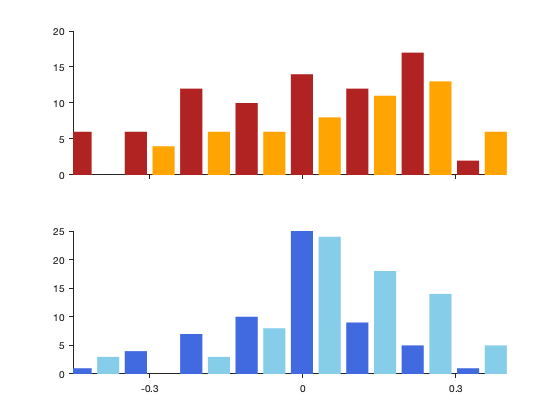

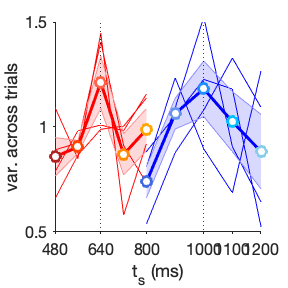

=====
figS6B


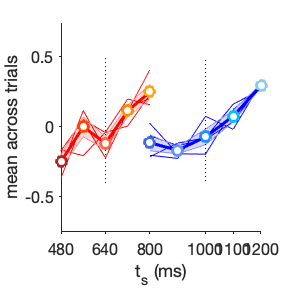

ans = 0.4609

ans = 0.1250

=====
figS6C


Xu vs Speed, pearsonC: -0.173, p:3.47e-20


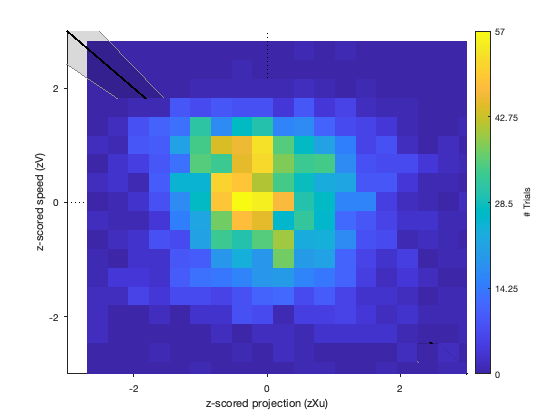

=====
figS6D
Speed vs tp, pearsonC: -0.0356, p:0.0597


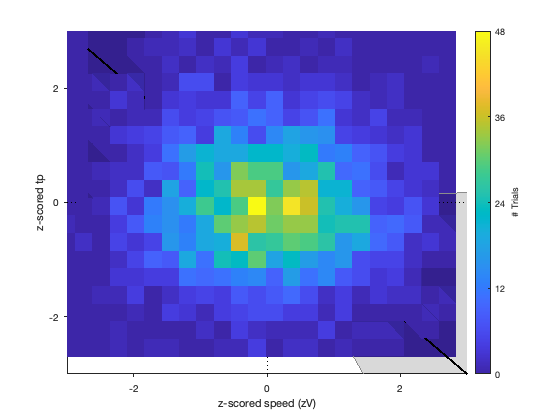

plot_xu(S); % figS6AB

function plot_xu(S) % figS6AB

v2struct(S);

anNm={'G'}; % {'G'}; % {'H'}; % 'G'; % {'H';'G'}; %'G'; % 'H'; % {'H';'G'}; % both animal
sessId={'170511'}; % {'170511'}; % {'161218'}; %{{'161218'};... % {{'161206';'161211';'161218';'161221';'161222';'161223'};... % H: 6 sessions
%     {'170506';'170507';'170511';'170818';'170821';'170822';'170823'}}; % G: 7 sessions

idGPFA=1;
idSqrt=1; % 0; % 1;
if idSqrt
    fnEnd2='_newUts_sqrtSingleT';
else
    fnEnd2='';
end

%% init
% perturbation parameters
idRandPerturb=0; % 1;
nRand=10000;
nCmap=256;
cmap=flipud(copper(nCmap)); % parula(nCmap);
lw=2;
msize=10;

% plot
cmapPr=[rgb('FireBrick'); rgb('RoyalBlue'); rgb('DarkGreen')]; %
cmapRot=[rgb('DeepPink'); rgb('Aqua')];
msize=4; % 10; % 4; % 6; % 2;
msize2=2;
lw=1.2; % 1; % 3; % 1.5;
optsExpFig.Width=6; optsExpFig.Height=6;
lw2=0.25;

% params in correlation
idCondSpec=  3; % 1; % if 2, pr/ts-specific; if 0, ignore conditions; if 3, z score projected states to combine across conditions
idRobustReg=false; % false; % true; % not used (even if true) if idRegModel==1
idRegModel=1; % for plotReg - idRegModel: 0 for no error in variable x, 1 otherwise

% params in crossVal_sess
idPCpoolSess=1; % 0; % 1; % session-specific PCA if 0
idIncEarly= 0; % idIncEarly in crossVal_sess.m
idUseScoreReadout= 1; % use score from leave-one-trial-out PSTH> if 0, use psthSess w/o cross validation to estimate readout
idAllSessReadout=0; % 1; % estimating readout vector from PC of all sessions: idAllSessReadout
idUseAvgAtt=1;

idAvgAttB4PCA=1; % 0; % 1; %%%%%%%%%%
idUseTIC=0; % 1;
idNotFullRecord= 0; % 1; % 0; % 1; %    if 1, including neurons with not fully recorded
if idNotFullRecord==1,
    nTrialIncNeuron_buffer=15; % threshold for including neurons with (total # trials - 15 trials)
    fnEnd=[];
else fnEnd='_cellFullOnly';
    nTrialIncNeuron_buffer=15; % 0; % 15; % threshold for including neurons with (total # trials - 15 trials)
end
if idAllSessReadout, fnEnd=[fnEnd '_allSessReadout']; end
nPC= 0; % 3; % if 0, use nPC(PVAF>75%)
idNewCenter=1;
idSave=1; % crossVal_sess_anal_randPerturb


if idPCpoolSess
    if idIncEarly
        if idUseScoreReadout
            d1=load(fullfile(singleTDir,'trajKS_161218_ts_pr_H_condSpec_poolSessNew_CV_avgAtt_newCenter.mat')); % D tp ts idPr idHandEye theta tIC sSet
        else
            d1=load(fullfile(singleTDir,'trajKS_161218_ts_pr_H_condSpec_poolSessNew_CV_avgAtt_newCenter_noUseScoreReadout.mat')); % D tp ts idPr idHandEye theta tIC sSet
        end
    else % idIncEarly
        if idUseAvgAtt
            if idNewCenter==1
                if idAvgAttB4PCA
                    if idNotFullRecord
                        d1=load(fullfile(singleTDir,['trajKS_' sessId '_pr_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA.mat'])); % D tp ts idPr idHandEye theta tIC sSet _newCenter
                        disp(['trajKS_' sessId '_pr_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA.mat']);disp(size(d1.D(1).W));
                        %                                             fnTmp=fullfile(singleTDir,['trajKS_' fid '_' epochNm{k} '_' animalNm{iAnimal} '_condSpec_poolSessNew_CV_avgAttB4PCA_' fnEnd '.mat']); % psthDir
                    else  %%%%% currently used
                        if idGPFA
                            d1=load(fullfile(singleTDir,['trajKS_' sessId{1} '_pr_' anNm{1} '_condSpec_GPFA_CV' fnEnd '.mat'])); % D tp ts idPr idHandEye theta tIC sSet _newCenter _cellFullOnly
                            disp(['trajKS_' sessId{1} '_pr_' anNm{1} '_condSpec_GPFA_CV' fnEnd '.mat']);
                        else
                            d1=load(fullfile(singleTDir,['trajKS_' sessId '_pr_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA' fnEnd fnEnd2 '.mat'])); % D tp ts idPr idHandEye theta tIC sSet _newCenter _cellFullOnly
                            disp(['trajKS_' sessId '_pr_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA' fnEnd fnEnd2 '.mat']);disp(size(d1.D(1).W));
                        end
                        %                                             fnTmp=fullfile(singleTDir,['trajKS_' fid '_' epochNm{k} '_' animalNm{iAnimal} '_condSpec_poolSessNew_CV_avgAttB4PCA_' fnEnd '.mat']); % psthDir
                    end
                end % idAvgAttB4PCA
            end
        else
        end
    end
    % tp
    if idUseTIC, fnEnd=[fnEnd '_idUseTIC']; end
    if idNewCenter==1
        if idUseScoreReadout
            if idAvgAttB4PCA
                if idNotFullRecord
                    d2=load(fullfile(singleTDir,['trajKS_' sessId '_t_p_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA' fnEnd '.mat'])); % D tp ts idPr idHandEye theta tIC sIC
                    disp(['trajKS_' sessId '_t_p_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA' fnEnd '.mat']);disp(size(d2.D(1).W));
                else  %%%%% currently used
                    if idGPFA
                        d2=load(fullfile(singleTDir,['trajKS_' sessId{1} '_tp_' anNm{1} '_condSpec_GPFA_CV' fnEnd '.mat'])); % D tp ts idPr idHandEye theta tIC sSet _newCenter _cellFullOnly
                        disp(['trajKS_' sessId{1} '_tp_' anNm{1} '_condSpec_GPFA_CV' fnEnd '.mat']);
                    else
                        d2=load(fullfile(singleTDir,['trajKS_' sessId '_t_p_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA' fnEnd '.mat'])); % D tp ts idPr idHandEye theta tIC sIC _newCenter_cellFullOnly
                        disp(['trajKS_' sessId '_t_p_' anNm '_condSpec_poolSessNew_CV_avgAttB4PCA' fnEnd '.mat']);disp(size(d2.D(1).W));
                    end
                end
            end
        else
            d2=load(fullfile(singleTDir,'trajKS_161218_ts_t_p_H_condSpec_poolSessNew_CV_avgAtt_newCenter_noUseScoreReadout.mat')); % D tp ts idPr idHandEye theta tIC sIC
        end
    else
    end
    
end

if idGPFA
    % readout vectors CV
    %     xro1=d1.xro'; % squeeze(struct2mat(d1.D,'xro')); % [6(maxDim) x 1610 trials]
    %     xro2=squeeze(struct2mat(d2.D,'xro'));
    
    idPr=d1.idPr; % 1 short 2 long
    tp=d1.tp;
    ts=d1.ts; tsId=nan(size(ts)); for iPr=1:nPr,for j=1:nTspp,tsId(T{iPr}(j)==ts & idPr==iPr)=j;end;end
    idHE=2-d1.idHandEye; % 0 hand 1 eye
    theta=d1.theta-1; % d1.theta==180; % 0 right 1 left
else
    % readout vectors CV
    xro1=squeeze(struct2mat(d1.D,'xro')); % [6(maxDim) x 1610 trials]
    xro2=squeeze(struct2mat(d2.D,'xro'));
    
    idPr=d1.idPr; % 1 short 2 long
    tp=d1.tp;
    ts=d1.ts; tsId=nan(size(ts)); for iPr=1:nPr,for j=1:nTspp,tsId(T{iPr}(j)==ts & idPr==iPr)=j;end;end
    idHE=d1.idHandEye; % 0 hand 1 eye
    theta=d1.theta==180; % 0 right 1 left
end

%% speed estimation
% for now, measure instantanious distance (c.f. KiNeT)
nTrial=length(d2.D);
v=nan(nTrial,1);
for iT=1:nTrial
    v(iT)=mean(sqrt(sum(diff(d2.D(iT).data,1,2).^2,1)));
end % iT=1:nTrial

sSet=[d1.sSet];
sSet=sSet(:);

sId=sessId{1};

idCond=(nEH*nTspp*nTarg)*(idPr-1)+(nEH*nTarg)*(tsId-1)+(1-idHE)*nTarg+theta+1; % short 480 eye right ...
% idCond=(nPr*nTspp*nTarg)*idHE+(nPr*nTspp)*theta+(idPr-1)*nTspp+(tsId-1)+1; % hand right short 480 ...

idPlot=0;
calcCorr(sSet,tp,ts,v,idCondSpec,idCond,idPr,tsId,idRobustReg,idRegModel,idPlot,sId,idHE,theta); % V); last for idPlot
% applytofig(gcf,optsExpFig);
% calcCorr(sSet,sIC,1,idCond,idPr,tsId,1,0,1);

end

%% main: calculating correlation
function [rMat,varargout]=calcCorr(sSet,tp,ts,v,idCondSpec,idCond,idPr,tsId,idRobustReg,idRegModel,idPlot,varargin) % V
% input: sSet,sIC,idCondSpec,idCond,idPr,tsId,tmpCmap,idRobustReg,condNm,xro1

% v2struct(V);
initRSG2prior; % condNm
lw2=0.1;

if ~isempty(varargin)
    sId=varargin{1}; % session ID to pool across sessions
    if ischar(sId)
        sId=str2num(sId);
    end
    idHE=varargin{2}; % 0 hand 1 eye
    theta=varargin{3}; % 0 right 1 left
    idCond2=(nEH*nTarg)*(idPr-1)+(1-idHE)*nTarg+theta+1; % short 480 eye right ...
    
end

IS=unique(sId); nS=length(IS); sId2=nan(size(sId)); % nominal sess Id
for iS=1:length(IS), sId2(sId==IS(iS))=iS; end
IC=unique(idCond); % [1:40]
IC2=unique(idCond2); % 1:8

Vset=nan(nS,length(IC2),nTspp);
Mset=nan(nS,length(IC2),nTspp);

if idCondSpec==3 % z scoring projected values to comibne across conditions
    
    % condition-specific z-scoring (not including ts)
    % + session-specific z scoring
    zSSet=nan(size(sSet)); zTp=nan(size(tp)); zV=nan(size(v));
    for iS=1:length(IS)
        for iC=1:length(IC2)
            tmpId=IC2(iC)==idCond2 & IS(iS)==sId;
            
            zSSet(tmpId)=zscore(sSet(tmpId));
            zTp(tmpId)=zscore(tp(tmpId));
            zV(tmpId)=zscore(v(tmpId));
            
            for iTs=1:nTspp
                tmpIdPr=1+((nEH*nTarg)<IC2(iC)); % 1 for short, 2 for long
                
                Mset(iS,iC,iTs)=nanmean(zSSet(tmpId & ts==T{tmpIdPr}(iTs)));
                Vset(iS,iC,iTs)=nanvar(zSSet(tmpId & ts==T{tmpIdPr}(iTs)));
            end
            
            % ROC analysis
            
        end
    end
    disp('=====');
    disp('figS6A inset');
    
    load('pplot.mat','tmpCmap');
    
    %% plot histogram (eye right)
    idStart=1; % eye right
    idHist=1; % 0; % 1;
    hFig=figure(123);ha; % rotation
    
    % get bin locations (common b/t short and long)
    nBin=20; % 10;
    barWidth=0.4;
    x=linspace(min(sSet),max(sSet),nBin);
    
    % set
    tmpIC=idStart:4:length(IC); % 1 5 9 ... 37
    xmeshDense=linspace(-4,4,500);
    for iC=1:length(tmpIC) % 1 2 3 ... 10
        tmpId=idCond==tmpIC(iC);
        iPr=1+(length(tmpIC)/2<iC); % 1 for short, 2 for long
        iTs=iC-length(tmpIC)/2*(iPr-1);
        subplot(2,1,iPr); ha;
        if iTs==1 | iTs==nTspp % rem(iTs,2)~=0 % only plot ts1, ts3, ts5
            if idHist
                hH=histogram(sSet(tmpId),x);
                Xval    = hH.BinEdges + hH.BinWidth*0.5 +hH.BinWidth*(iTs-(nTspp+1)/2)/8; % binWidth*0.25 for short, 0.75 for long
                Xval    = Xval(1:end-1);
                Yval    = hH.Values;
                delete(hH);
                hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',tmpCmap{iPr,1}(iTs,:),'EdgeColor','none');     ha;
                %                     histogram(sSet(tmpId),nBin,'DisplayStyle','stairs','edgecolor',tmpCmap{iPr,1}(iTs,:)); ha;
            else
                [bandwidth,density,xmesh,cdf]=kde(sSet(tmpId),2^5); % ,tmpMin,tmpMax);
                densityDense=ksdensity(sSet(tmpId),xmeshDense,'bandwidth',bandwidth/2);
                plot(xmeshDense,densityDense,'-','linewidth',0.5,'color',tmpCmap{iPr,1}(iTs,:)); ha;
            end
        end
    end % for iC=1:length(tmpIC)
    %%%%%
    xtickTmp=-.3:.3:.3;xlimTmp=[-0.45 0.4];
    subplot(2,1,1); set(gca,'xtick',xtickTmp,'xticklabel',[],'tickdir','out','ticklength',[0.01 0.01],'xlim',xlimTmp); box off; % ,'ytick',0:0.2:0.4
    subplot(2,1,2); set(gca,'xtick',xtickTmp,'tickdir','out','ticklength',[0.01 0.01],'xlim',xlimTmp); box off; % ,'ytick',0:0.2:0.4
    
    
    disp('=====');
    disp('figS6A');
    figure; ha;  box off;
    for iPr=1:nPr
        if iPr==nPr
            tmpIdPr=((nEH*nTarg)<(1:size(Vset,2))); % 0 for short, 1 for long (from 21)
        else
            tmpIdPr=((nEH*nTarg)>=(1:size(Vset,2))); % 1 for short (up to 20), 0 for long
        end
        tmpY=reshape(Vset(:,tmpIdPr,:),size(Vset,1)*size(Vset,2)/nPr,size(Vset,3)); % [nS*nC 5ts]
        plot(T{iPr}(:),tmpY',['-'],'color',round(pplot.cmap{(iPr-.5)*2}+0.4),'markerfacecolor','w','linewidth',lw2);drawnow; % pplot.marker8_2{im}
        % grand mean
        Vset2=squeeze(mean(tmpY,1)); % nan(nPr,nTspp);
        Vset3=squeeze(sem(tmpY,1));
        shadedErrorBar(T{iPr}(:),Vset2,Vset3,{['-'],'color',pplot.cmap{(iPr-.5)*2},'markerfacecolor','w','linewidth',lw,'markersize',msize},1);ha; drawnow; % pplot.marker8_2{im}
        plotVertical(gca,median(T{iPr}),[]);
        for iTs=1:nTspp
            plot(T{iPr}(iTs),Vset2(iTs),'o','color',tmpCmap{iPr,1}(iTs,:),'markerfacecolor','w','linewidth',2,'markersize',10);ha; drawnow; % pplot.marker8_2{im}
        end
    end
    set(gca,'xtick',unique([T{1}(1:2:end) T{2}(3:end)]),'ticklength',[0.01 0.01],'tickdir','out','ytick',-2:.5:2); % ,'ytick',-3:0.5:3
    xlabel('t_s (ms)'); ylabel('var. across trials');  axis tight; ylim([0.5 1.5]);
    applytofig4keynote; % applytofig4paper; %
    
    
    % condition-specific z-scoring
    for iC=1:length(IC)
        tmpId=IC(iC)==idCond;
        
        sSet(tmpId)=zscore(sSet(tmpId));
        tp(tmpId)=zscore(tp(tmpId));
        v(tmpId)=zscore(v(tmpId));
    end
    rMat1=[];
    [r1,p1]=corr(sSet(:),v(:));
    rMat1=[rMat1;r1];
    rMat2=[];
    [r2,p2]=corr(v(:),tp(:));
    rMat2=[rMat2;r2];
    
    disp('=====');
    disp('figS6B');
    %% plot mean var Xu
    figure; ha;  box off;
    dTmpY=[]; slope=cell(nPr,1);
    for iPr=1:nPr
        if iPr==nPr
            tmpIdPr=((nEH*nTarg)<(1:size(Mset,2))); % 0 for short, 1 for long (from 21)
        else
            tmpIdPr=((nEH*nTarg)>=(1:size(Mset,2))); % 1 for short (up to 20), 0 for long
        end
        tmpY=reshape(Mset(:,tmpIdPr,:),size(Mset,1)*size(Mset,2)/nPr,size(Mset,3)); % [nS*nC 5ts]
        dTmpY=[dTmpY; diff(tmpY,1,2)];
        for jCond=1:size(tmpY,1), tmpB=regress(tmpY(jCond,:)',[ones(nTspp,1) T{iPr}(:)]); slope{iPr}=[slope{iPr}; tmpB(2)]; end
        plot(T{iPr}(:),tmpY',['-'],'color',round(pplot.cmap{(iPr-.5)*2}+0.4),'markerfacecolor','w','linewidth',lw2);drawnow; % pplot.marker8_2{im}
        % grand mean
        Mset2=squeeze(mean(tmpY,1)); % nan(nPr,nTspp);
        Mset3=squeeze(sem(tmpY,1));
        shadedErrorBar(T{iPr}(:),Mset2,Mset3,{['-'],'color',pplot.cmap{(iPr-.5)*2},'markerfacecolor','w','linewidth',lw,'markersize',msize},1);ha; drawnow; % pplot.marker8_2{im}
        plotVertical(gca,median(T{iPr}),[]);
        for iTs=1:nTspp
            plot(T{iPr}(iTs),Mset2(iTs),'o','color',tmpCmap{iPr,1}(iTs,:),'markerfacecolor','w','linewidth',2,'markersize',10);ha; drawnow; % pplot.marker8_2{im}
        end
    end
    set(gca,'xtick',unique([T{1}(1:2:end) T{2}(3:end)]),'ticklength',[0.01 0.01],'tickdir','out','ytick',-2:.5:2);
    xlabel('t_s (ms)'); ylabel('mean across trials'); axis tight; ylim([-0.75 0.75]);
    applytofig4keynote;
    % stat
    signrank(mean([dTmpY(:,1) dTmpY(:,end)],2),mean([dTmpY(:,2) dTmpY(:,3)],2)) % [2pr*4cond 4dTp]
    signrank(slope{1},slope{2},'tail','right')
    
    
    nBin=25; nCmap=256;
    cmap=parula(nCmap); % flipud(copper(nCmap));
    disp('=====');
    disp('figS6C');
    hFig=figure;ha;
    disp(['Xu vs Speed, pearsonC: ' num2str(r1,3) ', p:' num2str(p1,3)]);
    [N,xedges,yedges]=histcounts2(sSet(:),v(:),nBin);
    colormap(cmap);
    tmpX=xedges(1:(end-1)); %+diff(xedges)/2;
    tmpY=yedges(1:(end-1)); % +diff(yedges)/2;
    surf(tmpY,tmpX,N,'linewidth',lw,'EdgeAlpha',0); % ,'ShowText','on')
    axis tight;
    s=plotReg(sSet(:),v(:),hFig,zeros(1,3),idRobustReg,idRegModel); % 'beta','yhat','r','rsquare','tstat'
    colormap(cmap);
    hBar2=colorbar; hBar2.Label.String='# Trials';
    set(hBar2,'Ticks',round(linspace(min(N(:)),max(N(:)),5)*100)/100); % ,'TickLabels',round(linspace(min(rMat),max(rMat),5)*100)/100);
    xlabel('z-scored projection (zXu)'); ylabel('z-scored speed (zV)'); axis tight; plotVertical(gca,0,[]); plotHorizon(gca,0,[]);
    set(gca,'xtick',-2:2:2,'ytick',-2:2:4,'tickdir','out'); %%%%%
    axis([-3 3 -3 3]);
    %         applytofig(gcf,optsExpFig);
    
    hFig2=figure;ha;
    disp('=====');
    disp('figS6D');
    disp(['Speed vs tp, pearsonC: ' num2str(r2,3) ', p:' num2str(p2,3)]);
    [N,xedges,yedges]=histcounts2(v(:),tp(:),nBin);
    colormap(cmap);
    tmpX=xedges(1:(end-1)); %+diff(xedges)/2;
    tmpY=yedges(1:(end-1)); % +diff(yedges)/2;
    surf(tmpY,tmpX,N,'linewidth',lw,'EdgeAlpha',0); % ,'ShowText','on')
    axis tight;
    s=plotReg(v(:),tp(:),hFig2,zeros(1,3),idRobustReg,idRegModel); % 'beta','yhat','r','rsquare','tstat'
    colormap(cmap);
    hBar2=colorbar; hBar2.Label.String='# Trials';
    set(hBar2,'Ticks',round(linspace(min(N(:)),max(N(:)),5)*100)/100); % ,'TickLabels',round(linspace(min(rMat),max(rMat),5)*100)/100);
    xlabel('z-scored speed (zV)'); ylabel('z-scored tp'); axis tight; plotVertical(gca,0,[]); plotHorizon(gca,0,[]);
    set(gca,'xtick',-2:2:2,'ytick',-2:2:4,'tickdir','out'); %%%%%
    axis([-3 3 -3 3]);
    %         applytofig(gcf,optsExpFig);
end


end

